# Create Building Animation

partFileXML = "building_with_solar_load.xml";
[apartment3D, geoLocation, dateTimeVec] = readBuildingDataXML(partFileXML);

    {'Location:Bengaluru'}

Simulation Duration:
*** Start Time :01-May-2024 01:00:00
*** End Time   :07-May-2024 01:00:00
*** Room Names in Building : Bathroom,Kitchen,BedRoom,LivingRoom


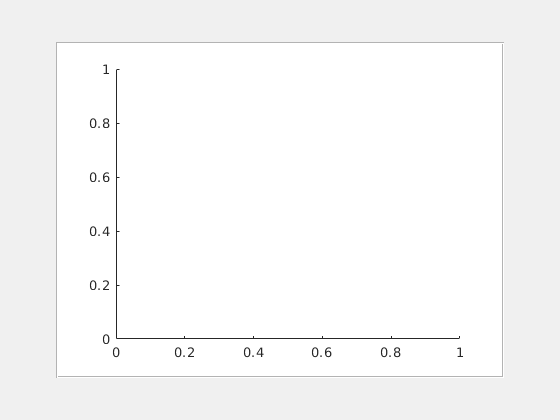

viewingAngle = [-1 -1 1]; 

f  = figure("Name","Building Data");
p  = uipanel(f,"Position",[0.1 0.1 0.8 0.8],"BackgroundColor","w");
ax = axes(p);

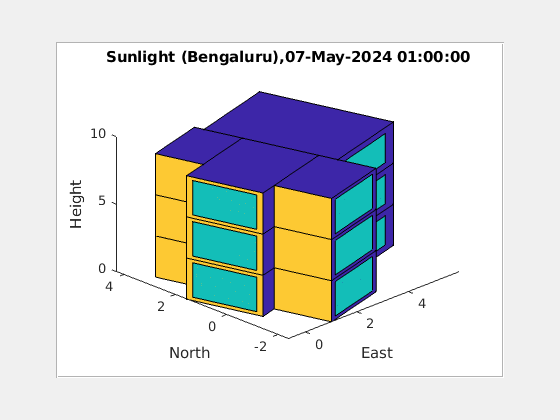

updateFreqHrs = 1;
for nHrs = 1:updateFreqHrs:length(dateTimeVec)
    plot3DlayoutBuilding(apartment3D,viewingAngle,"sunlight",nHrs);
    dateTimeVal = dateTimeVec(1,nHrs);
    colorbar("off");
    title(strcat('Sunlight (',geoLocation.Row,'), ',string(dateTimeVal)));
    recordAnimationData(1,nHrs) = getframe(gcf);
end

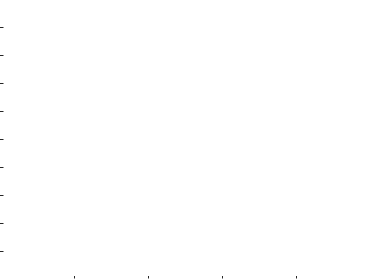


figure
axes("Position",[0 0 1 1])
movie(recordAnimationData,1,1)